# Lab 2: 2D Convolution & FIR Filters (Blur, Sharpen, Edges)

Course: Mathematical Algorithms (DSP) — Image Processing Labs - Kernel = impulse response h[m,n]. - Prefer Gaussian over large box for smoother frequency response. - Discuss separability (two 1D passes) and boundary handling. HOW TO SUBMIT: include screenshots and short explanations for each section in the GitHub. Submit only the GitHub URL. -------------------------------------------------------------------------

close all; clear; clc;
if exist('peppers.png','file')
    I0 = imread('peppers.png');
else
    I0 = repmat(imread('cameraman.tif'),1,1,3);
end
I = im2double(rgb2gray(I0));

## 1) Delta image & impulse response

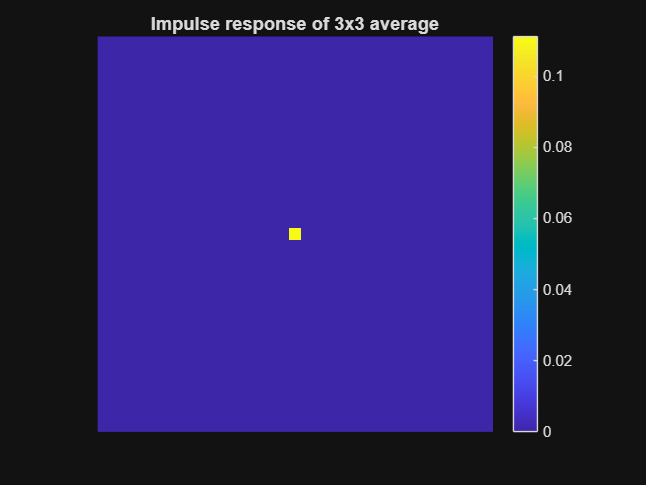

delta = zeros(101,101); delta(51,51) = 1;
h_avg = ones(3,3)/9;
H_vis = conv2(delta, h_avg, 'same');
figure; imagesc(H_vis); axis image off; colorbar; title('Impulse response of 3x3 average');

## 2) Low-pass: box vs Gaussian, separability

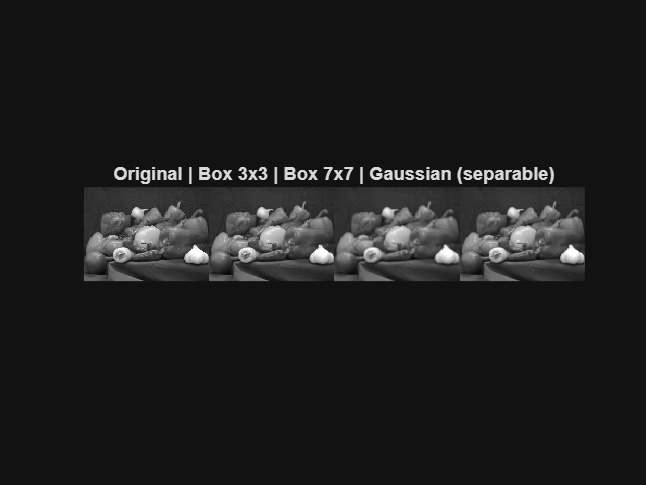

h_box3 = ones(3,3)/9;
h_box7 = ones(7,7)/49;
sigma = 1.2;
g1d = fspecial('gaussian',[1 7], sigma);
h_gauss = g1d'*g1d; % separable
I_box3 = imfilter(I, h_box3, 'replicate');
I_box7 = imfilter(I, h_box7, 'replicate');
I_gauss = imfilter(I, h_gauss, 'replicate');
figure; montage({I, I_box3, I_box7, I_gauss},'Size',[1 4]);
title('Original | Box 3x3 | Box 7x7 | Gaussian (separable)');

## 3) Unsharp masking (sharpen)

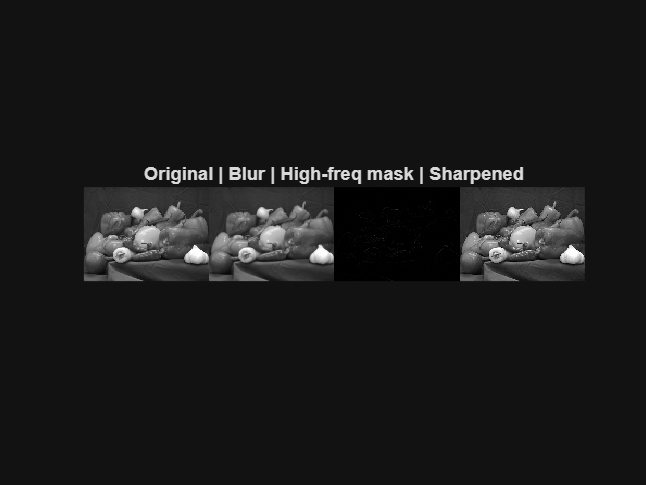

I_blur = imfilter(I, h_gauss, 'replicate');
mask = I - I_blur; % high-frequency
gain = 1.0;
I_sharp = max(min(I + gain*mask,1),0);
figure; montage({I, I_blur, mask, I_sharp},'Size',[1 4]);
title('Original | Blur | High-freq mask | Sharpened');

## 4) Edges: Sobel & Laplacian

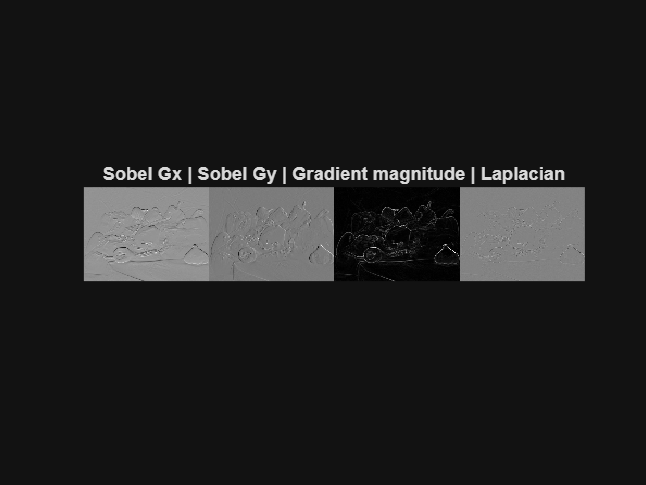

h_sobel_x = fspecial('sobel');
h_sobel_y = h_sobel_x';
Gx = imfilter(I, h_sobel_x, 'replicate');
Gy = imfilter(I, h_sobel_y, 'replicate');
Gmag = hypot(Gx, Gy);
h_lap = fspecial('laplacian', 0.2);
I_lap = imfilter(I, h_lap, 'replicate');
figure; montage({mat2gray(Gx), mat2gray(Gy), mat2gray(Gmag), mat2gray(I_lap)},'Size',[1 4]);
title('Sobel Gx | Sobel Gy | Gradient magnitude | Laplacian');

## 5) Correlation vs convolution (kernel flip)

C1 = conv2(I, h_box3, 'same');
C2 = imfilter(I, h_box3, 'conv', 'same'); % 'conv' flips internally
diff_val = max(abs(C1( : )-C2( : )));
fprintf('Max difference (conv2 vs imfilter with conv): %g\n', diff_val);

Max difference (conv2 vs imfilter with conv): 3.33067e-16


## 6) Boundary handling

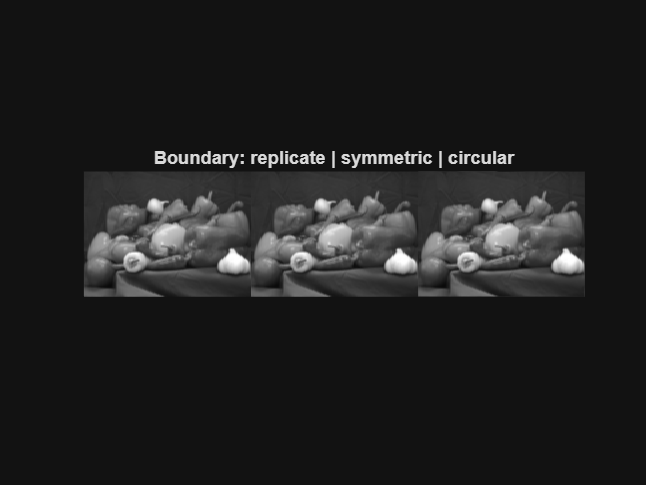

I_rep = imfilter(I, h_box7, 'replicate');
I_sym = imfilter(I, h_box7, 'symmetric');
I_cir = imfilter(I, h_box7, 'circular');
figure; montage({I_rep, I_sym, I_cir},'Size',[1 3]);
title('Boundary: replicate | symmetric | circular');

## 7) Reflections

1) Why is Gaussian preferred over large box LP? 

Because Gaussian processes the image by making pixels near the processed pixel have larger impact on it, making the image look smoother on the edges.

2) What does separability do for computational cost? 

Separability lowers the cost a lot. A 2D filter can be applied as two 1D filters instead of one full 2D convolution.

3) How do boundary modes change corners/edges?

The circular one looks a bit better compared with the other two, but the difference is insignificant.